# s_oeBloodFluorophoreTongueSrch 

The notes are in s_oeBloodFluorophoreLipSrch.mlx.

From 500-600n, there is an excellent fit with the {'collagen1','KeratinPalero','FADLin'} fluorophores.  The deviation is mainly with the 450nm excitation light.  We think there was some light leaking through.  Joyce actually knows.  When we do the fits from 520-600 nm, even the 450 nm excitation light nails the data perfectly.

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
[T,dataDir] = oeDatabaseCreate;

## Create fluorophore matrix and read database 

We create the base fluorophore emissions matrix.  It does not include blood (fluorophoresB).  Below, we sweep through different potential levels of blood optical density, checking how well the modified fluorophore matrix predicts the data samples.  Notice that the effective optical density of blood can depend on the wavelength of the excitation light.  Some lights will penetrate into the skin (substrate) more deeply than others, thus creating a longer path through the blood.

We tried many fluorophore files from the literature. These are described in in **s_oeFluorophoreEmissions.mlx**.  

Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  They exact emissions differ between labs, but the slopes are similar.

For the lip, there is no keratin, porphyrins, or chlorophyll.  We selected which to use in the s_oeBloodFluorophoreBasis.mlx script.

**Things we tried.**

- fluorophoreNames = {'collagen1','FAD_webfluor'}; -  Not enough dimensions. Fails to fit the data closely.

- fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor','NADH_webfluor'}; - Never chooses elastin

- fluorophoreNames = {'collagen1','FAD_webfluor','KeratinValdez'}; - Replaced NADH with Keratin.  Removed elastin. Too flat around 540, and a deep dive around 580.  General slope is OK.

- fluorophoreNames = {'collagen1','KeratinValdez','FADValdez'}; - Way off. Doesn't even get an OK fit of the blood.

- fluorophoreNames = {'CollagenWuQu','FADLin'}; - Way off, as above. Fails with blood

- fluorophoreNames = {'CollagenWuQu','FADValdez'}; - Way off as above.

- fluorophoreNames = {'CollagenWuQu','FAD_webfluor'}; - FIt is bad, but the blood is OK.

- fluorophoreNames = {'CollagenWuQu','elastin_webfluor','FADValdez'}; - Another blood miss.

- fluorophoreNames = {'collagen7','elastin_webfluor','FADValdez'}; - This collagen is goofy, and the fits are bad including the blood.

**Our winners so far**

- fluorophoreNames = {'CollagenWuQu','NADH_webfluor','FADLin'}; - Best fit so far.  

- fluorophoreNames = {'collagen1','NADH_webfluor','FADLin'}; - Still good if we swap collagen1 for ColalgenWuQu.  That's a good thing.  

- fluorophoreNames = {'collagen1','KeratinPalero','FADLin'}; -  This keratin is close to NADH

We should also try deoxygenated blood at some point, by adding in a collagen-deoxy column.

fluorophoreNamesB = {'collagen1','KeratinPalero','FADLin'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## 405/415 nm excitation

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);
odError = zeros(numel(odLevels),numel(subjects));  
ods = zeros(numel(subjects),1);    
rmse = zeros(size(subjects));

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405,'e level',980);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415,'e level',910);
    tongueFiles = cat(1,files405,files415);

    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);    
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 16.00
OD across subjects for 405/415nm 15.00
OD across subjects for 405/415nm 15.00
OD across subjects for 405/415nm 16.00


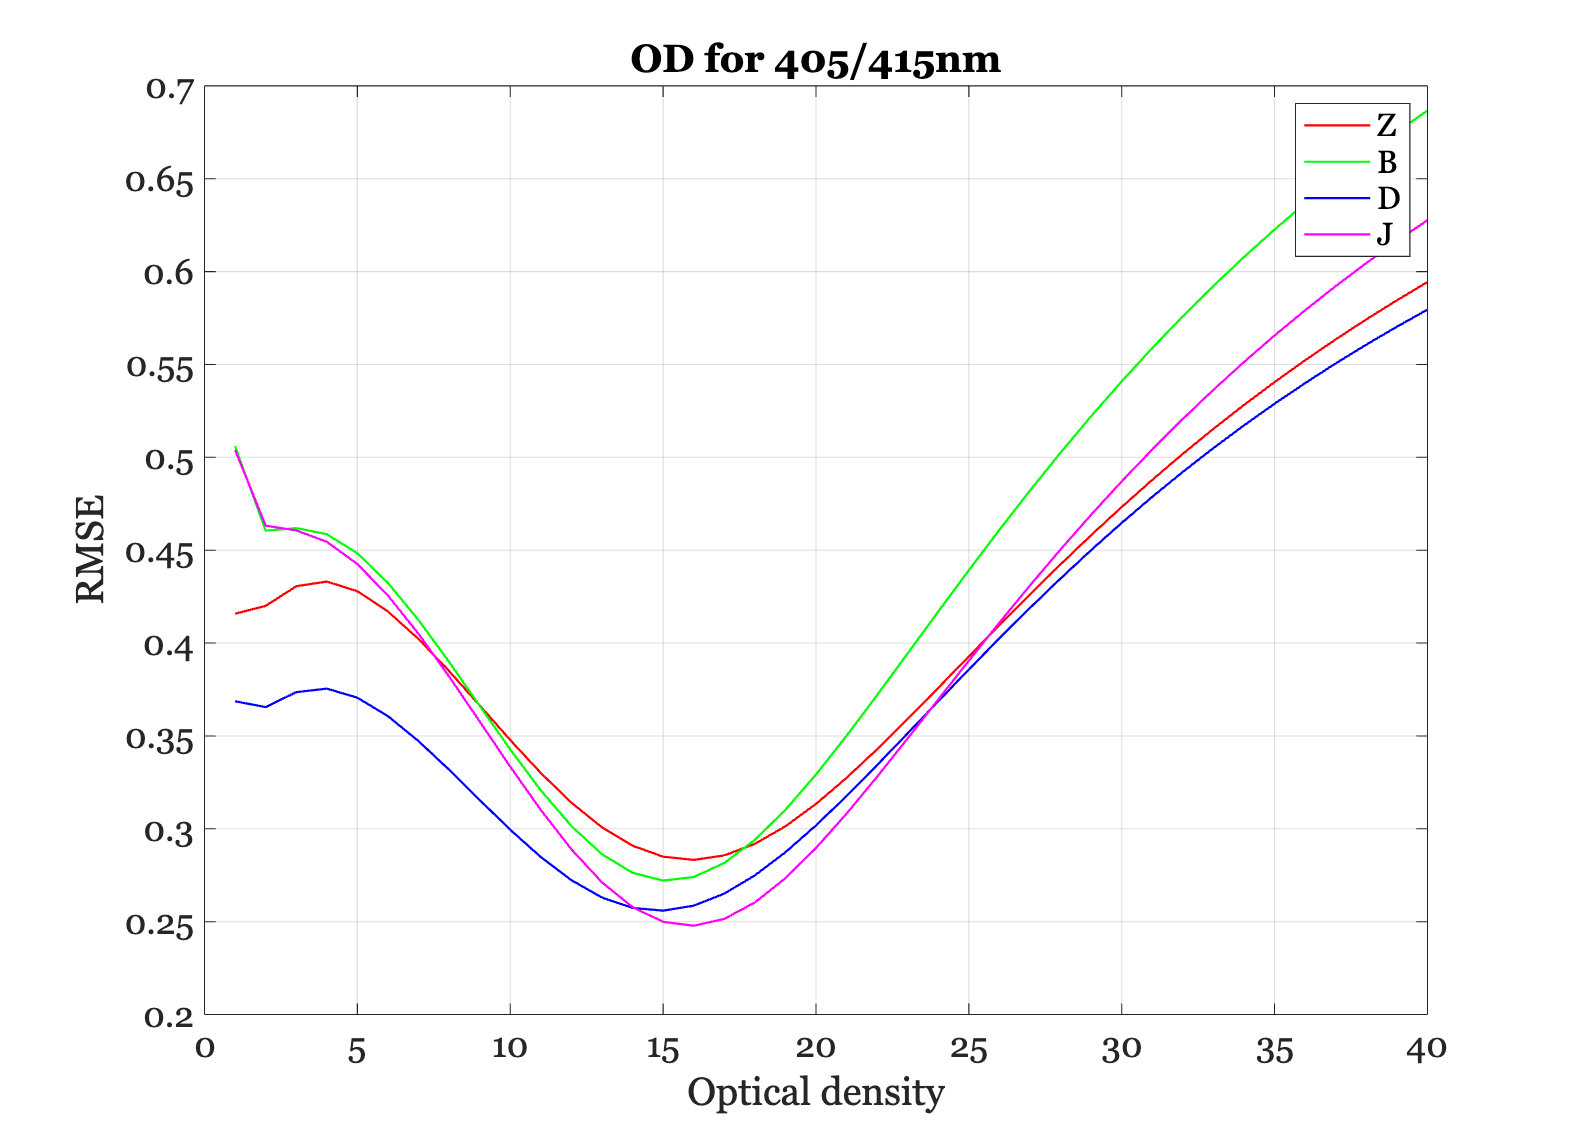


% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 405/415nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Apply the proper optical density and plot

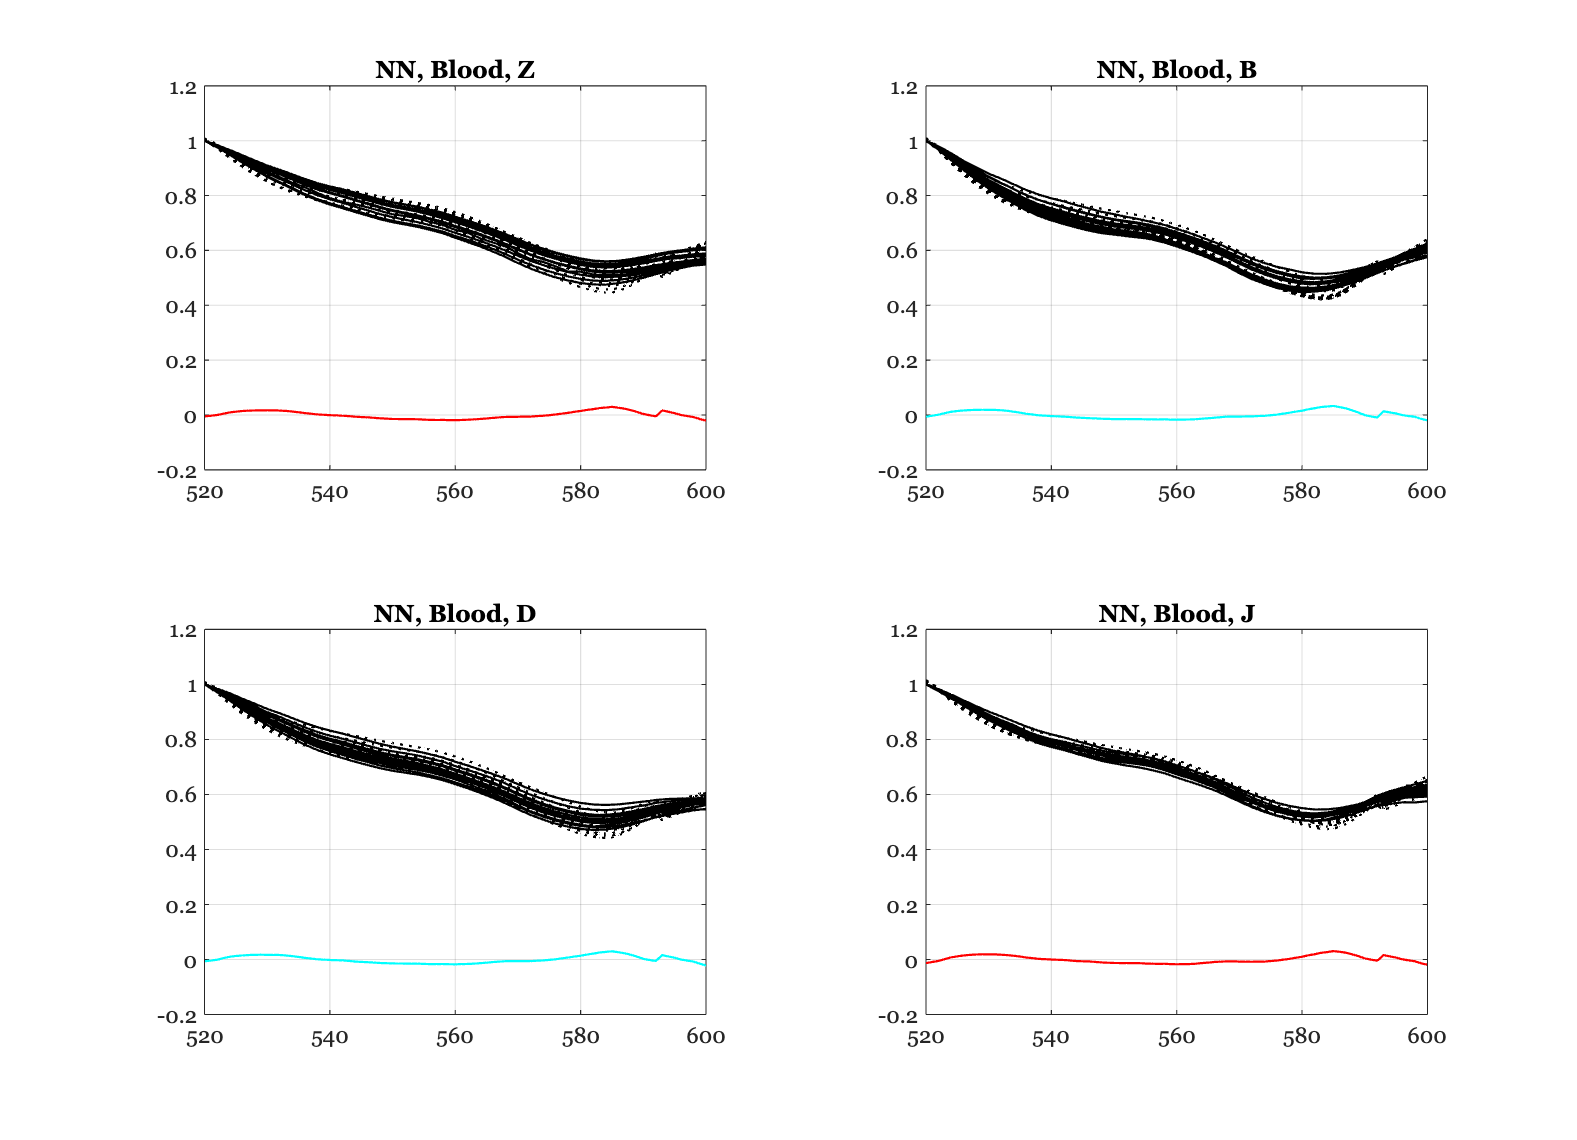

Subject Z
    5.7588    5.5645    3.7085    6.9774    3.6407    3.5235    3.6987    4.0299    3.4376    3.4902    4.4233    6.5063    4.3739    4.7708    5.1941
    0.7853    0.7715    0.7621    0.7965    0.6821    0.7299    0.6824    0.7556    0.7126    0.7273    0.6903    0.8233    0.7726    0.7657    0.7613
    0.4615    0.4752    0.4932    0.4419    0.5480    0.5170    0.5498    0.4955    0.5307    0.5219    0.5352    0.4253    0.4914    0.4922    0.4933
    6.5453    6.6654    8.6482    5.8110    9.2351    9.3336    8.6057    8.6096    9.0810    8.8678    8.4765    7.2861    6.9837    6.8431    6.0101

Subject B
    6.9356    3.0618    4.9631    8.7607    6.6830    7.6017    7.3273    8.7386    6.6772    7.5463    6.6801    6.9522    5.8266    6.8586
    0.7461    0.7386    0.7358    0.7623    0.7791    0.7878    0.7959    0.7613    0.7831    0.7836    0.7990    0.7637    0.7579    0.7499
    0.4286    0.4813    0.4618    0.3868    0.4013    0.3860    0.3890    0.3946    0.4049   

ieFigure;
tiledlayout(2,2);

deoxyblood = medium('deoxy_molarExtinctionCoefficient.mat','wave',wave);
deoxyblood.opticalDensity = 5;

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames]  = oeApplyBlood(fluorophoresB,fluorophoreNamesB,...
        oxyblood, ...
        'deoxy',deoxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end
    residual = tongueData - fluorophores*wgtsNN;
    rmse(ii) = norm(residual(:),2);

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:', ...
        wave,mean(residual,2));
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

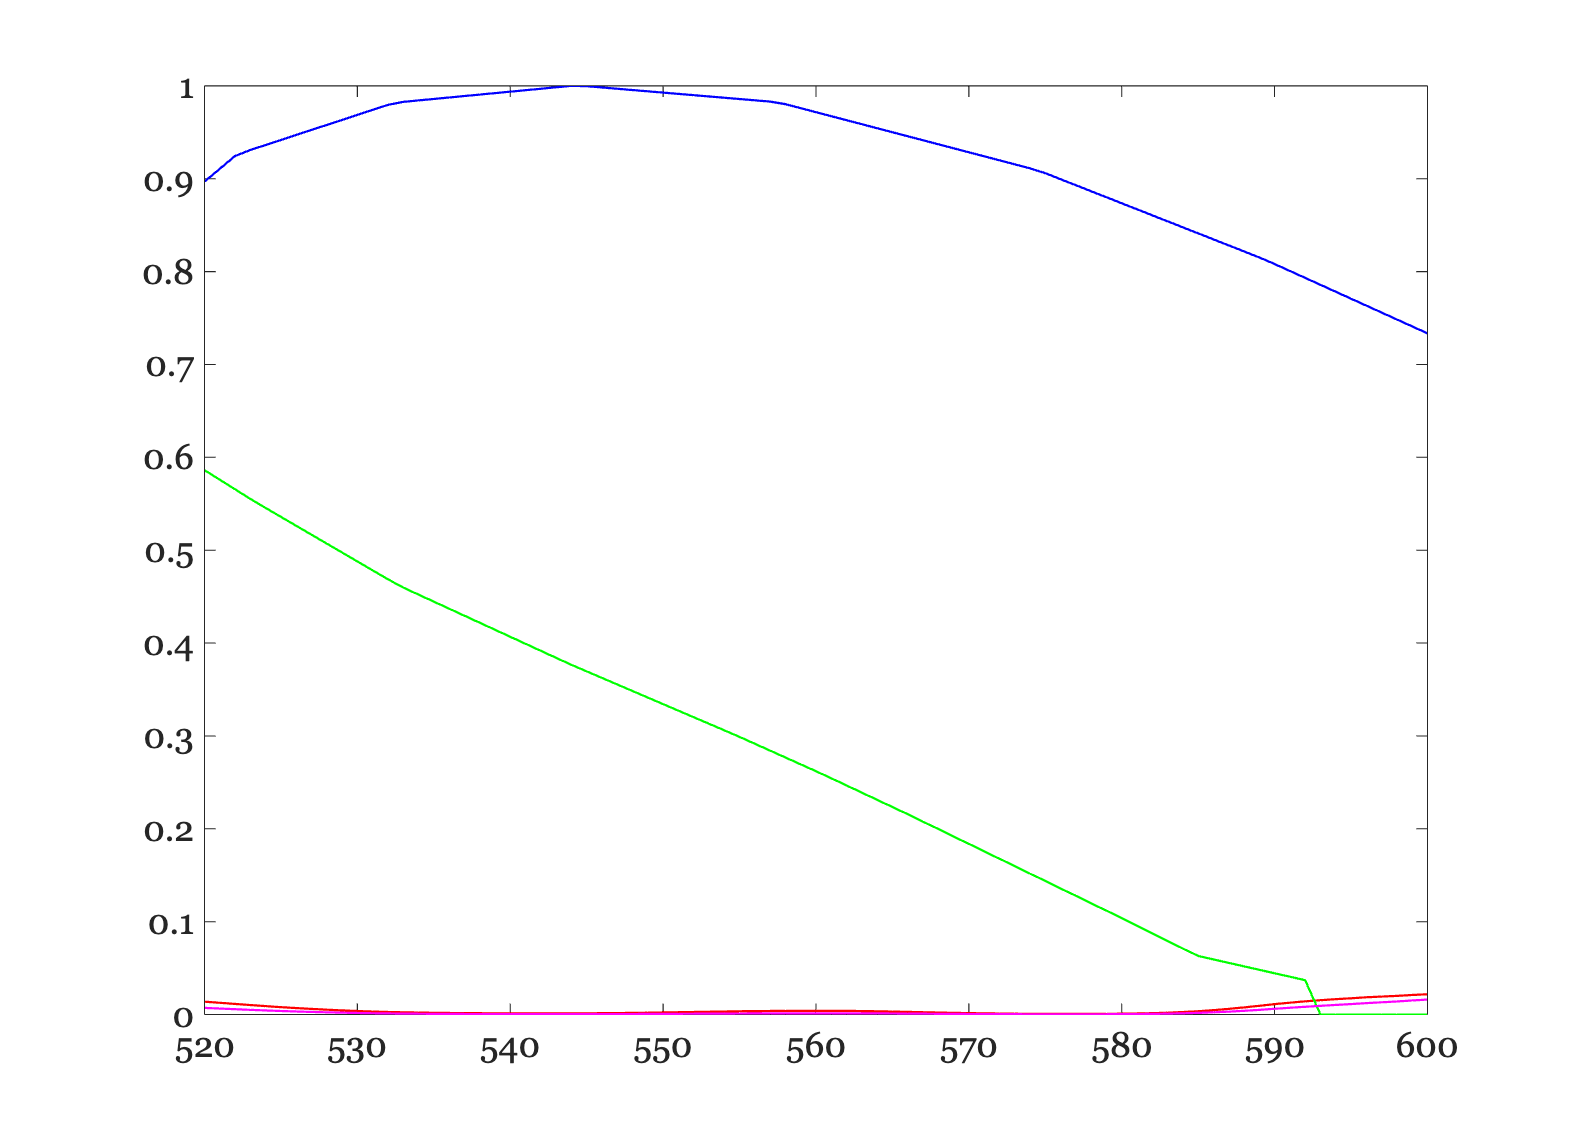

ieFigure; plot(wave,fluorophores);

    
disp(rmse); disp(fluorophoreNames);

    0.4685    0.4726    0.4451    0.4636

    {'collagen1-oxy'}    {'KeratinPalero'}    {'FADLin'}    {'collagen1-deoxy'}



## Create 450 nm blood optical density levels

odError = zeros(numel(odLevels),numel(subjects));

for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},...
        'substrate','tongue',...
        'e wave',450);
    tongueData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 18.00
OD across subjects for 405/415nm 18.00
OD across subjects for 405/415nm 17.00
OD across subjects for 405/415nm 17.00


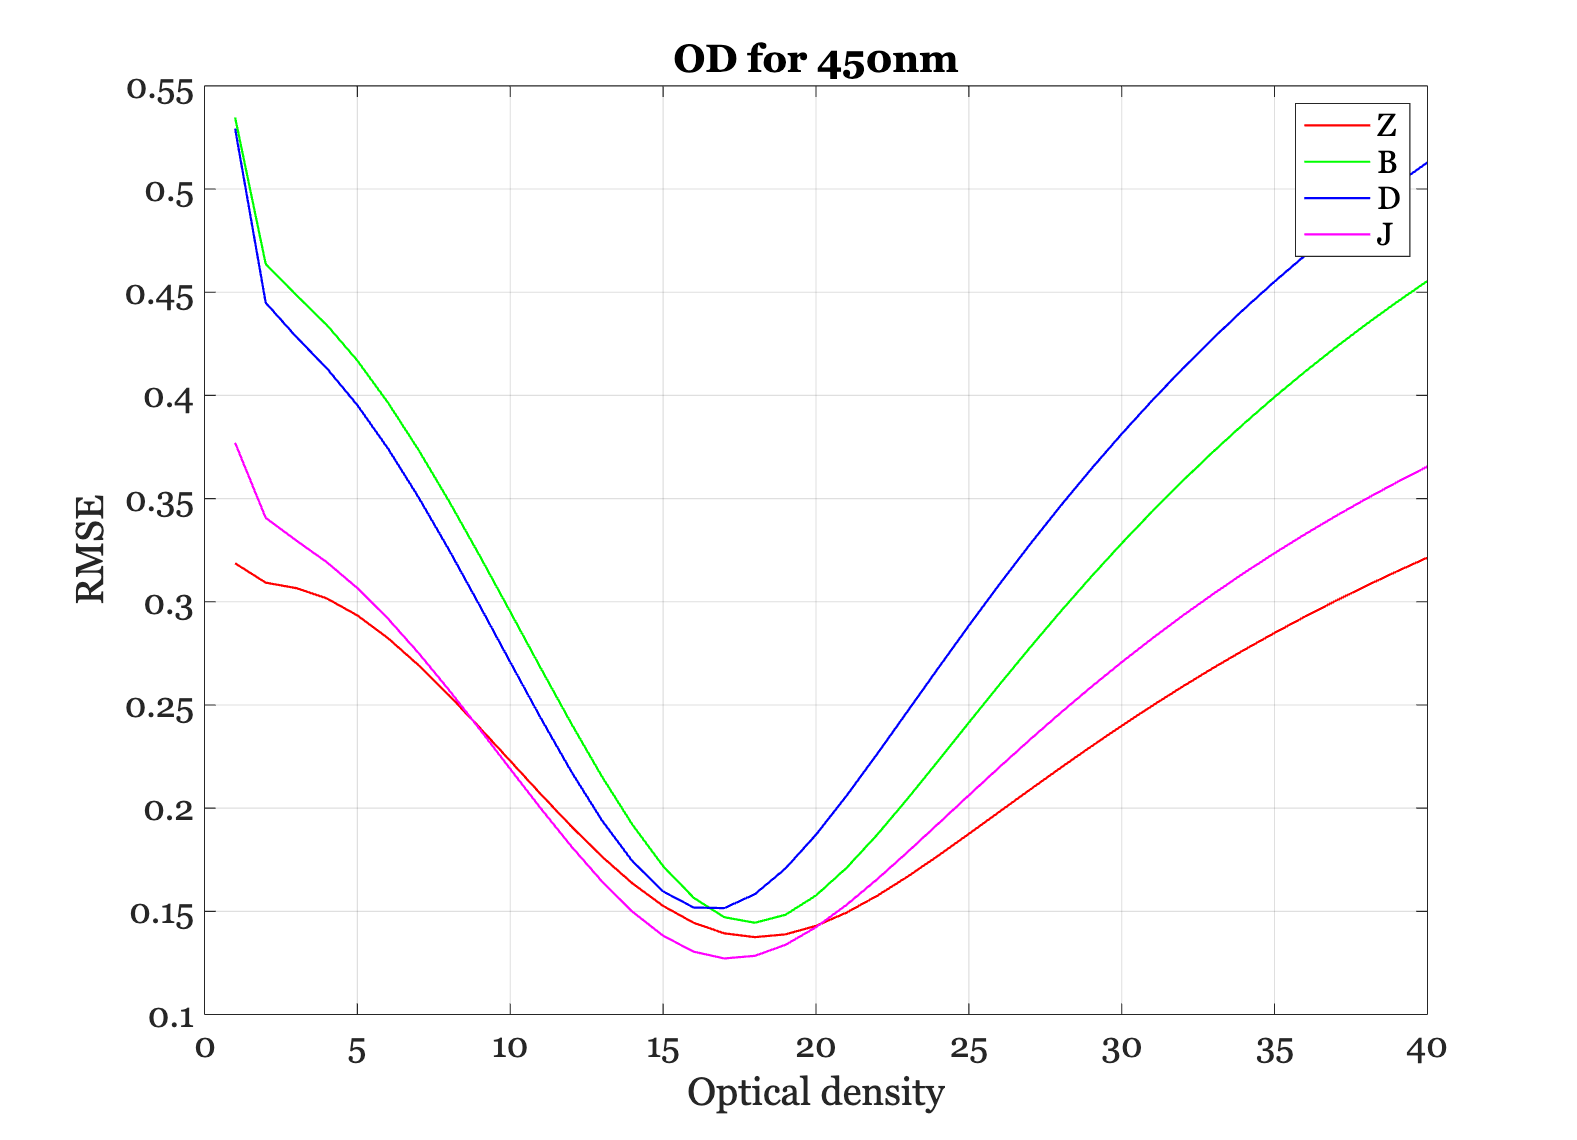



% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 450nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## 450 nm excitation light

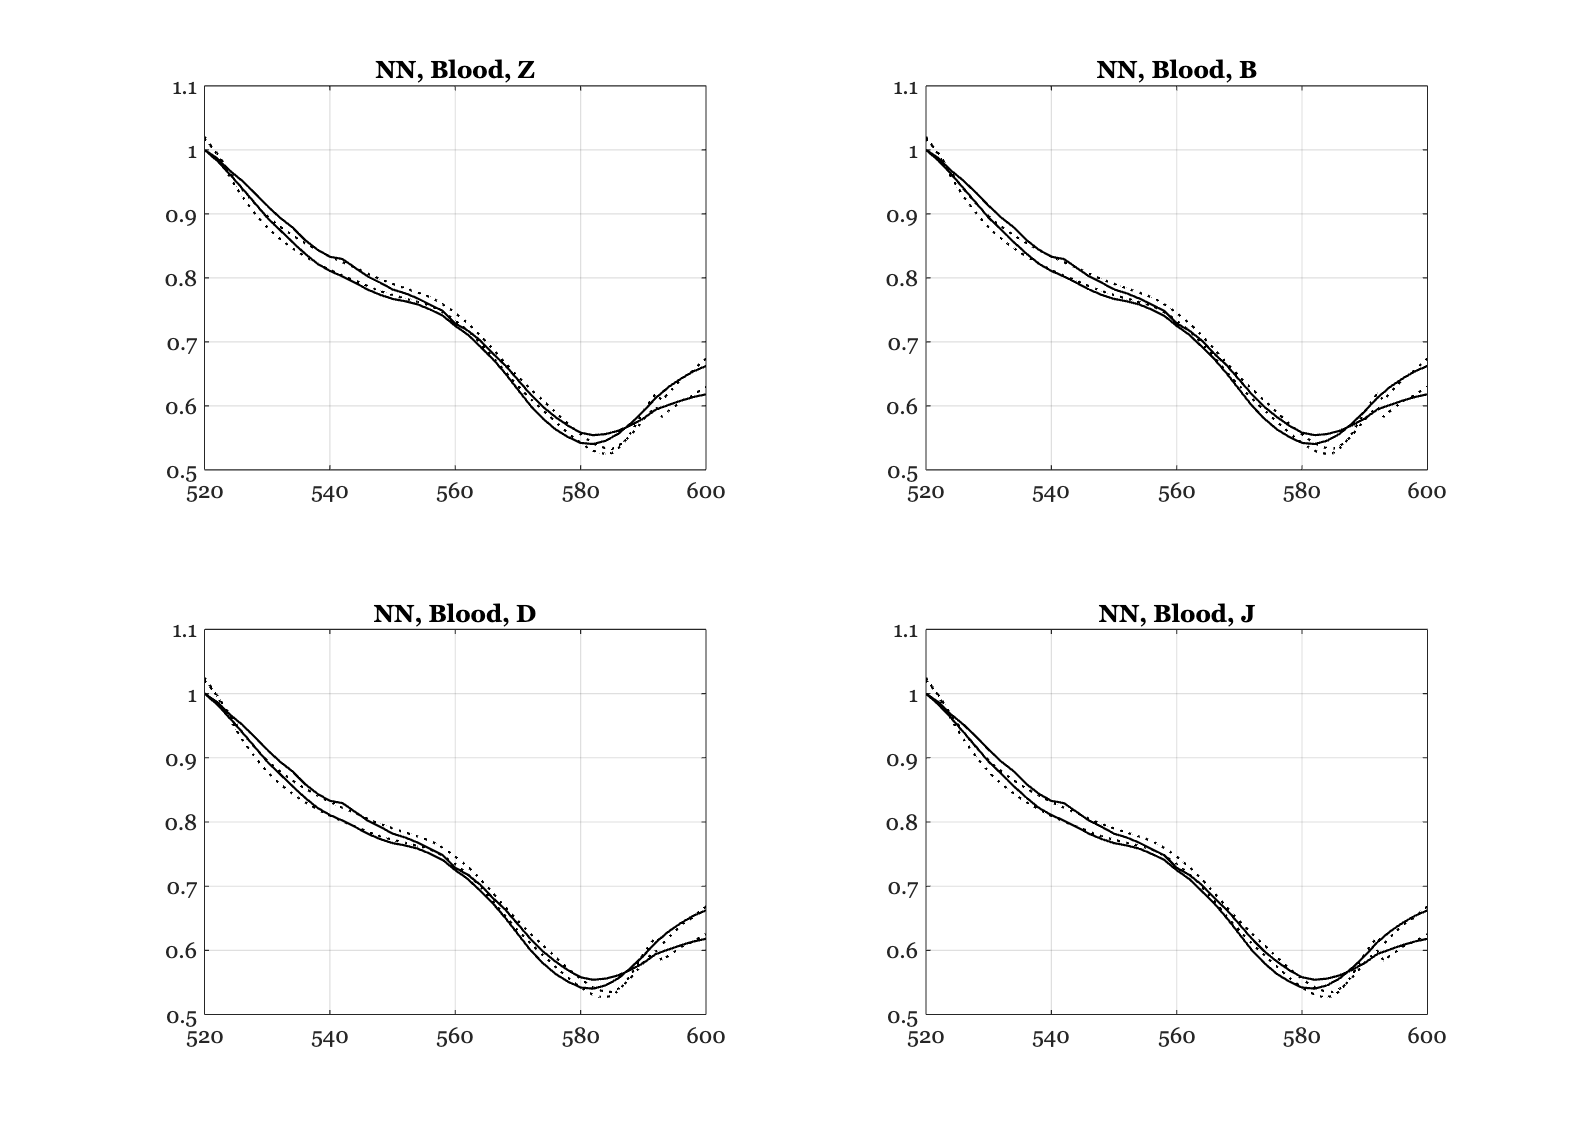

Subject Z
   13.3280   10.7565
    0.6729    0.6939
    0.5315    0.5461

Subject B
   13.3280   10.7565
    0.6729    0.6939
    0.5315    0.5461

Subject D
   12.9015   10.4113
    0.6611    0.6844
    0.5311    0.5458

Subject J
   12.9015   10.4113
    0.6611    0.6844
    0.5311    0.5458



ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)
    wgtsNN = zeros(size(fluorophoresB,2),size(tongueData,2));

    oxyblood.opticalDensity = ods(ii);
    fluorophores = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end